# Chapter 3

clear all;
close all;
clc;

%------------------------------------------------------------

## 2 - The 2D-DFT

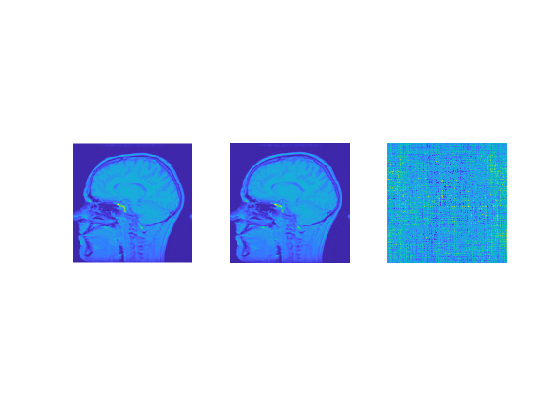

fid = fopen('head.128','r');
[x,npels] = fread(fid,[128,128],'uchar');
x = x';
fclose(fid);
figure(1);
subplot(1,3,1);imagesc(x);axis square; axis off;

Fx=fft2(x);
iFx=ifft2(Fx);

subplot(1,3,2);imagesc(iFx);axis square; axis off;

difference=x-iFx;
subplot(1,3,3);imagesc(difference);axis square; axis off;



SE=difference(:).^2;
% 
% figure;
% hist(SE,50);
SSE=sum(SE)

SSE = 1.3195e-24

#### 2.1-Visualising the basis images

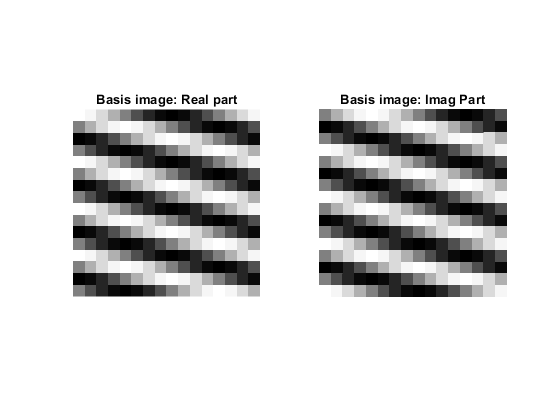

Im=zeros(16,16);
Im(5,10)=1;

B = ifft2(fftshift(Im));

figure;
subplot(1,2,1);imagesc(real(B));colormap(gray);title('Basis image: Real part');axis square; axis off;
subplot(1,2,2);imagesc(imag(B));colormap(gray);title('Basis image: Imag Part');axis square; axis off;


dot_product=sum(real(B).*imag(B),'all') % =0 thus orthogonal

dot_product = 0

#### 2.2 - Energy Compaction Property

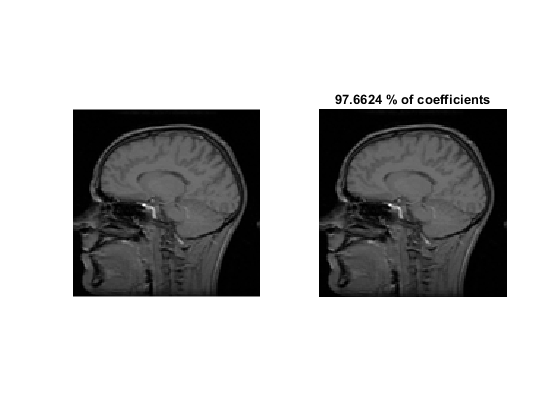

[sorted_Fx,I] = sort(abs(Fx(:)),'descend');

array_coeff=zeros(size(Fx));

figure;
subplot(1,2,1)
imagesc(x);colormap(gray);axis square;axis off;
error_tracker=[];

for n_coeff=1:200:16001
    array_coeff(I(n_coeff:n_coeff+199))=Fx(I(n_coeff:n_coeff+199))';
    ydash=ifft2(array_coeff')';
    subplot(1,2,2)
    imagesc(real(ydash));colormap(gray);axis square;axis off;
    fraction=100*n_coeff/length(Fx(:)) ;
    title([num2str(fraction),' % of coefficients']);
    pause(0.1);
    diff=double(x)-real(ydash);
    error=sqrt(mean(diff(:).^2)/mean(x(:).^2));
    error_tracker=[error_tracker; [fraction,error]];
end

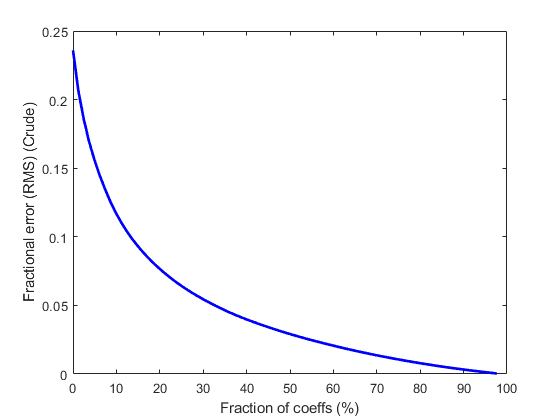


figure;
plot(error_tracker(:,1),error_tracker(:,2),'b',"LineWidth",2);
xlabel('Fraction of coeffs (%)');
ylabel('Fractional error (RMS) (Crude)');